% Heat transfer coefficients
h_i = 15; % W/m^2-K
h_o = 25; % W/m^2-K
h_window = 0.7; % W/m^2-K ==== equivalent based on inner pane to outerpane 

% Specific heats
rho_tile = 3000; % kg/m^3
c_tile = 800; % J/kg-K
rho_air = 1.2; % kg/m^3 ==== from QEA book 3.2
c_air = 1000; % J/kg-K ==== from QEA book 3.2

% Conductivities
k_fiberglass = 0.04; % W/m-K

% House dimensions
depth = 5; % m
length_tile = 5.1; % m
height_window = 3; % m
control_length = 0.9; % m
height_fiberglass = 3; % m
length_fiberglass = 5.1; % m
thickness_fiberglass = 0.1; % m

% Areas
area_tile = depth * length_tile; % m^2
area_window = depth * height_window; % m^2
area_under_house = depth * (length_tile + 2*thickness_fiberglass); % m^2
area_fiberglass_inside = 2*height_fiberglass*length_fiberglass ...
                         + height_fiberglass * depth ...
                         + length_fiberglass * depth; % m^2
area_fiberglass_outside = 2*(height_fiberglass + 2 * thickness_fiberglass)*(length_fiberglass + 2 * thickness_fiberglass)...
                         + (height_fiberglass + 2 * thickness_fiberglass) * (depth + 2 * thickness_fiberglass) ...
                         + (length_fiberglass + 2 * thickness_fiberglass) * (depth + 2 * thickness_fiberglass); % m^2

% Resistances
R_floor_to_air = (h_in * area_tile)^-1; % K/W
R_floor_to_outside = (thickness_fiberglass / k_fiberglass / area_tile) ...
                     + (h_out * area_under_house); % K/W
R_air_to_outside = (h_i * area_fiberglass_inside)^-1 ...
                    + (thickness_fiberglass / k_fiberglass / area_fiberglass_inside) ...
                    + (h_o * area_fiberglass_outside)^-1; % K/W
R_air_w_outside = (h_i * area_window)^-1 ...
                    + (h_window * area_window)^-1 ...
                    + (h_o * area_window)^-1; % K/W

% The given solar flux function
f_solar_flux = @(t) -361 * cos(pi * t/(12 * 3600)) + 224 * cos(pi * t/(6 * 3600)) + 210;
f_outside_air = @(t) -3 + 6*sin( (2*pi*t)/(24*3600) + 3*pi/4 );
f_radiation_length = @(angle) min([cotd(angle) * (height_window - control_length*tand(angle)); length_tile]);
% also use sunAngle

days = 3;
tspan = linspace(0, days*24*3600, 100);

figure()
yyaxis left
plot(tspan, f_solar_flux(tspan));
ylabel("Solar flux")

yyaxis right
plot(tspan, f_outside_air(tspan), '--');
ylabel("Outside air temperature")
title("Outside Conditions")

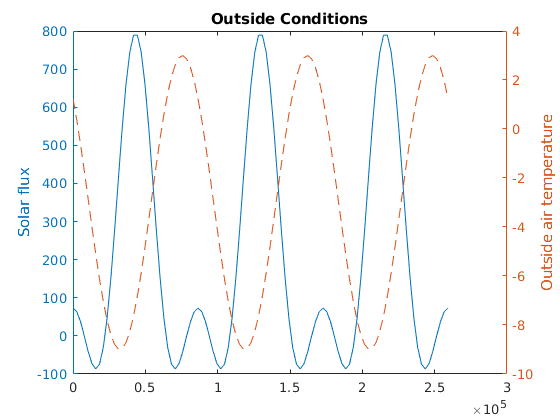

dT_floor/dt = f_solar_flux(t) * f_radiation_length(90 - sunAngle(day_of_year, hour)) * depth ...
          - (T_floor - T_air)/R_floor_to_air - (T_floor - T_outside)/R_floor_to_outside;
dT_air/dt = (T_floor - T_air)/R_floor_to_air - (T_air - T_outside)/R_air_w_outside - (T_air - T_outside)/R_air_to_outside;